# Inverted pendulum

The physical setup

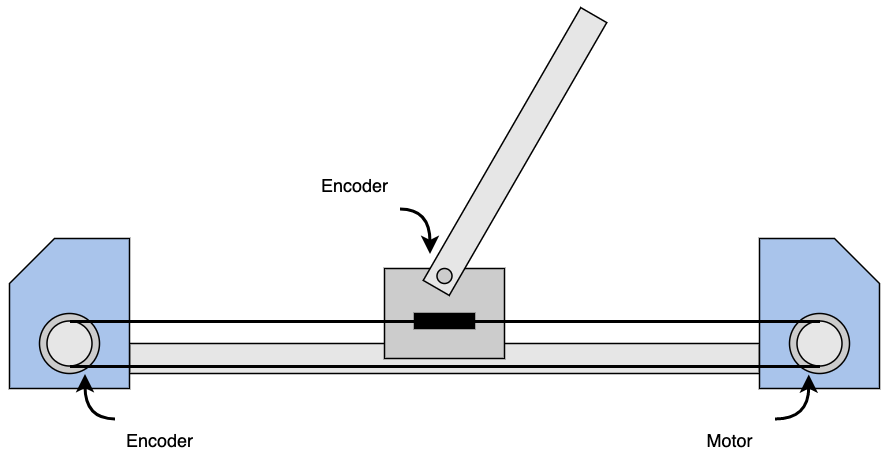

## System modelling

### Cart free body diagram

Note: The following free cart body diagram should probably also have gravity and normal force included. But as a sloppy conclusion, the normal force must equal the sum of V and w.

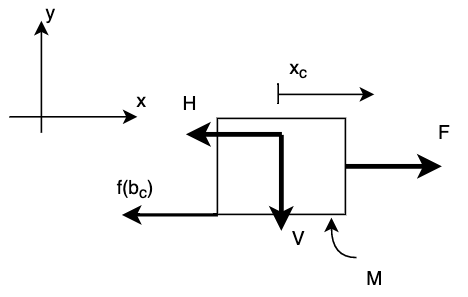

Using Newton's second law in the horizontal direction:

$M\ddot{\;x_c } \;=F-H-b_c \dot{\;x_c }$ (1)

The cart is assumed to not move in the vertical direction.

### Pendulum free body diagram

CHANGE THE DIAGRAM... THE TORQUE FRICTION IS IN THE WRONG DIRECTION!!

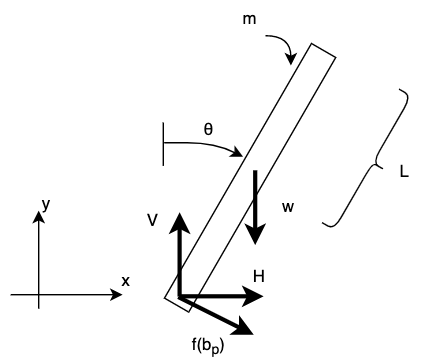

The center of gravity of the pendulum changes as the cart moves. It is given by:


$$c_{g,x} =x_c +L\;\cos \left(\theta \right)$$
 
$$c_{g,y} =L\;\sin \left(\theta \right)$$


Summing up the torque on the pendulum:

$J_p \ddot{\;\theta \;} =\left(-L\;H\;\cos \left(\theta \right)+L\;V\;\sin \left(\theta \;\right)+L\;b_p \dot{\theta \;} \right)$ (2)

Summing up the forces in the vertical direction gives:

$V-m\;g+b_p \dot{\;\theta } \sin \left(\theta \right)=m\;L\;\ddot{\;\sin \left(\theta \right)} \;$(3)

Some calculus:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\sin \left(\theta \right)=\;\frac{\mathrm{d}}{\mathrm{d}t}\cos \left(\theta \right)\;=-\sin \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}t}\theta =-\sin \left(\theta \right)\dot{\;\theta } \Rightarrow \frac{d^2 }{\mathrm{d}t^2 }\sin \left(\theta \right)=-\sin \left(\theta \right)\ddot{\;\theta } -\cos \left(\theta \right){\;\dot{\;\theta \;} }^2$$


% -sin(theta)*ddtheta - cos(theta)*dtheta^2
% cos(theta)*ddtheta - sin(theta)*dtheta^2

Using the result from above in (3) 

$V-m\;g+b_p \dot{\;\theta } \sin \left(\theta \right)=m\;L\;\left(-\sin \left(\theta \right)\ddot{\;\theta } -\cos \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)$(4)

Summing up the forces in the horizontal direction gives:

$H-b_p \;\dot{\theta} \;\cos \left(\theta \right)=m\ddot{x_c } +\textrm{mL}\ddot{\;\cos \left(\theta \;\right)}$ (5)

Some calculus:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\cos \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}t}\sin \left(\theta \right)\;=\cos \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}t}\theta =\cos \left(\theta \right)\dot{\;\theta } \Rightarrow \frac{d^2 }{\mathrm{d}t^2 }\cos \left(\theta \right)=\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2$$


Using the result form above in (5)

$H-b_p \;\dot{\theta} \;\cos \left(\theta \right)=m\ddot{x_c } +\textrm{mL}\left(\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)$(6)

From (6) and (4) we get expressions for H and V:

$V=m\;g-b_p \dot{\;\theta } \sin \left(\theta \right)-m\;\textrm{Lsin}\left(\theta \right)\ddot{\;\theta } -m\;\textrm{Lcos}\left(\theta \right){\;\dot{\;\theta \;} }^2$(7)

$H=b_p \;\dot{\theta} \;\cos \left(\theta \right)+m\ddot{x_c } +\textrm{mLcos}\left(\theta \right)\ddot{\;\theta } -\textrm{mLsin}\left(\theta \right){\;\dot{\;\theta \;} }^2$(8)

Substituting (7) and (8) into (1) and (2) reveals the non linear system:


$$M\ddot{\;x_c } \;=F-b_p \;\dot{\theta} \;\cos \left(\theta \right)-m\ddot{x_c } -\textrm{mLcos}\left(\theta \right)\ddot{\;\theta } +\textrm{mLsin}\left(\theta \right){\;\dot{\;\theta \;} }^2 -b_c \dot{\;x_c }$$



$$\left(M+m\right)\ddot{x_c } =u-b_p \;\dot{\theta} \;\cos \left(\theta \right)-m\;L\;\cos \left(\theta \right)\ddot{\;\theta } +m\;\textrm{Lsin}\left(\theta \right){\;\dot{\;\theta \;} }^2 -b_c \dot{\;x_c }$$


$\ddot{\;x_c } =\frac{1}{M+m}\left(u-b_p \;\dot{\theta} \;\cos \left(\theta \right)-m\;L\;\cos \left(\theta \right)\ddot{\;\theta } +m\;\textrm{Lsin}\left(\theta \right){\;\dot{\;\theta \;} }^2 -b_c \dot{\;x_c } \right)$ (s1)

clear all;
syms theta dtheta ddtheta xc dxc ddxc i di M m L g Jp bp bc u H V F Rm Lm kt ke Jm Bm r;
bp = 0;
% % Pendulum parameters
% M = 0.632;
% m = 0.181;
% L = 0.365/2;
% g = 9.82;
% Jp = 1/12*m*(2*L)^2;
% r = 12e-3/2;
% % Motor parameters
% Rm = 3.3;
% Lm = 1.25e-3;
% kt = 0.0285;
% ke = kt;
% Jm = 1.12e-6;
% Bm = 6.56e-5;

eq1 = M * ddxc == F - H - bc * dxc;
eq2 = Jp * ddtheta == -L * H * cos(theta) + L * V * sin(theta) - L * bp * dtheta;
eq3 = V == m * g + bp  * dtheta * sin(theta) + m * L * (-sin(theta)*ddtheta - cos(theta)*dtheta^2);
eq4 = H == m * ddxc + m * L * (cos(theta)*ddtheta - sin(theta)*dtheta^2);
eq5 = Jm*(ddxc/r) + Bm * ddxc == kt * i;
eq6 = Lm * di + Rm*i == u - ke * dxc/r;
eq7 = F == kt * i / r;

eq1 = subs(eq1, H, rhs(eq4))

$$eq1 = M\,\mathrm{ddxc}=F-\mathrm{bc}\,\mathrm{dxc}-\mathrm{ddxc}\,m+L\,m\,\left({\mathrm{dtheta}}^{2}\,\sin\left(\theta \right)-\mathrm{ddtheta}\,\cos\left(\theta \right)\right)$$

eq2 = subs(eq2, H, rhs(eq4));
eq2 = subs(eq2, V, rhs(eq3))

$$eq2 = \mathrm{Jp}\,\mathrm{ddtheta}=L\,\sin\left(\theta \right)\,\left(g\,m-L\,m\,\left(\cos\left(\theta \right)\,{\mathrm{dtheta}}^{2}+\mathrm{ddtheta}\,\sin\left(\theta \right)\right)\right)-L\,\cos\left(\theta \right)\,\left(\mathrm{ddxc}\,m-L\,m\,\left({\mathrm{dtheta}}^{2}\,\sin\left(\theta \right)-\mathrm{ddtheta}\,\cos\left(\theta \right)\right)\right)$$

eq5

$$eq5 = \mathrm{Bm}\,\mathrm{ddxc}+\frac{\mathrm{Jm}\,\mathrm{ddxc}}{r}=i\,\mathrm{kt}$$

eq6

$$eq6 = \mathrm{Lm}\,\mathrm{di}+\mathrm{Rm}\,i=u-\frac{\mathrm{dxc}\,\mathrm{ke}}{r}$$

eq7

$$eq7 = F=\frac{i\,\mathrm{kt}}{r}$$


yes = solve(eq6, i)

$$yes = -\frac{\mathrm{Lm}\,\mathrm{di}-u+\frac{\mathrm{dxc}\,\mathrm{ke}}{r}}{\mathrm{Rm}}$$

%eq7 = subs(eq7, i, solve(subs(eq5, i, solve(eq6, i)), i))
% sol = solve([eq1 eq2 eq5 eq6 eq7], [ddtheta ddxc di i F]);
% sol
sol = solve([eq1 eq2 eq7], [ddtheta ddxc di])

sol = struct with fields:
    ddtheta: [0×1 sym]
       ddxc: [0×1 sym]
         di: [0×1 sym]



$$M\;\ddot{\;x_c \;} =F-b_c \dot{\;x_c } -m\ddot{\;x_c } +L\;m\left({\dot{\;\theta \;} }^2 \;\sin \left(\theta \right)-\ddot{\;\theta \;} \cos \left(\theta \right)\right)$$



$$J_p \ddot{\;\theta } =L\;\sin \left(\theta \right)\left(g\;m+b_p \;\dot{\theta} \;\sin \left(\theta \right)-L\;m\;\left(\cos \left(\theta \right){\dot{\;\;\theta \;} }^2 +\ddot{\theta} \;\sin \left(\theta \right)\right)\right)-L\;\cos \left(\theta \right)\;\left(\ddot{\;x_c } \;m-L\;m\;\left({\dot{\;\;\theta \;} }^2 \;\sin \left(\theta \;\right)\;\ddot{\;\theta \;} \cos \left(\theta \right)\right)\right)-L\;b_p \dot{\theta}$$




x0 = [pi/3 0 0 0];
dt = 0.001;
T = 3;
t = 0:dt:T;
THETA = [x0(1) zeros(1,length(t)-1)];
XC = [x0(2) zeros(1,length(t)-1)];
DTHETA = [x0(3) zeros(1,length(t)-1)];
DXC = [x0(4) zeros(1,length(t)-1)];
U = zeros(1,length(t));
Mc = 2;
Mp = 1;
LP = 0.5;
G = 9.82;
BP = 0;
BC = 20;
for i = 2:length(t)
  %ddtheta = (3*(- L*m*cos(theta)*sin(theta)*dtheta^2 - u*cos(theta) + g*m*sin(theta) + M*g*sin(theta) + bc*dxc*cos(theta)))/(L*(- 3*m*cos(theta)^2 + 4*M + 4*m));
  %ddxc    = (4*L*m*sin(theta)*dtheta^2 + 4*u - 4*bc*dxc - 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);
  DDTHETA = subs(sol.ddtheta,[theta, xc, dtheta, dxc, u, M, m, L, g, bp, bc], [THETA(i-1), XC(i-1), DTHETA(i-1), DXC(i-1), U(i-1), Mc, Mp, LP, G, BP, BC]);
  DDXC = subs(sol.ddxc,[theta, xc, dtheta, dxc, u, M, m, L, g, bp, bc], [THETA(i-1), XC(i-1), DTHETA(i-1), DXC(i-1), U(i-1), Mc, Mp, LP, G, BP, BC]);

  DTHETA(i) = DTHETA(i-1)+DDTHETA*dt;
  DXC(i) = DXC(i-1)+DDXC*dt;
  THETA(i) = THETA(i-1)+DTHETA(i)*dt;
  XC(i) = XC(i-1)+DXC(i-1)*dt;
end

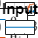

figure;
subplot(2,1,1);
plot(t,180/pi*mod(THETA,2*pi));
hold on;
grid on;
plot(t,180/pi*DTHETA);
l = legend('\theta','\theta_d');
title('\theta evolution');
subplot(2,1,2);
plot(t,U);
title('Input');

figure;
subplot(2,1,1);
plot(t,XC);
hold on;
grid on;
plot(t,DXC);
l = legend('x_c','x_{c_d}');
title('\theta evolution');
subplot(2,1,2);
plot(t,U);
title('Input');

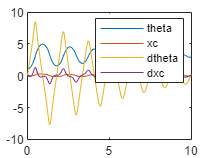

x0 = [pi/3 0 0 0];
[t,y] = ode45(@ode1,[0 10], x0);
figure;
plot(t,y)
legend('theta','xc','dtheta','dxc')



syms theta dtheta ddtheta xc dxc ddxc M m L g Jp bp bc u;
M = 2;
m = 1;
L = 0.5;
g = 9.82;
bp = 0;
bc = 1;
u = 0;
Jp = 1/3*m*L^2;
% eq1 = ddxc == 1/(M+m)*(u - bp*dtheta*cos(theta)-m*L*cos(theta)*ddtheta+m*L*sin(theta)*dtheta^2-bc*dxc);
% eq2 = ddtheta == 1/(Jp+m*L^2)*(L*m*g*sin(theta)-L*m*ddxc*cos(theta)-L*bp*dtheta*cos(2*theta));
% sol = solve([eq1 eq2], [ddtheta ddxc]);
% sol.ddtheta
% sol.ddxc
eq1 = ddxc == 1/(M+m)*(u-bp*dtheta*cos(theta)-m*L*cos(theta)*ddtheta+m*L*sin(theta)*dtheta^2-bc*dxc);
eq2 = ddtheta == 1/(Jp+m*L^2)*(L*m*g*sin(theta)-L*m*ddxc*cos(theta)+L*bp*dtheta);
sol = solve([eq1 eq2], [ddtheta ddxc]);
sol.ddtheta

$$ans = -\frac{-25\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+1473\,\sin\left(\theta \right)+50\,\mathrm{dxc}\,\cos\left(\theta \right)}{25\,\left({\cos\left(\theta \right)}^{2}-4\right)}$$

sol.ddxc

$$ans = \frac{-100\,\sin\left(\theta \right)\,{\mathrm{dtheta}}^{2}+200\,\mathrm{dxc}+1473\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{150\,\left({\cos\left(\theta \right)}^{2}-4\right)}$$

ddtheta_e = sol.ddtheta;
ddxc_e = sol.ddxc;

% Jp = 1/12*m*L^2;
% eq1 = (M+m)*ddxc + bc*dxc+m*L*ddtheta*cos(theta)-m*L*dtheta^2*sin(theta) == u;
% eq2 = (Jp+m*L^2)*ddtheta+m*g*L*sin(theta) == -m*L*ddxc*cos(theta);
% sol = solve([eq1 eq2], [ddtheta ddxc])
% sol.ddtheta




$$J_p \ddot{\;\theta \;} =\left(-L\;H\;\cos \left(\theta \right)+L\;V\;\sin \left(\theta \;\right)+Lb_p \dot{\theta \;} \right)$$



$$-L\;H\;\cos \left(\theta \right)={+L\;b}_p \;\dot{\theta} \;{\cos \left(\theta \right)}^2 -L\;m\;\ddot{x_c } \cos \left(\theta \right)-{m\;L}^2 \ddot{\;\theta } {\cos \left(\theta \right)}^2 +{m\;L}^2 {\dot{\;\theta \;} }^2 \sin \left(\theta \right)c\textrm{os}\left(\theta \right)$$



$$L\;V\;\sin \left(\theta \right)=L\;m\;g\;\sin \left(\theta \right)+{L\;b}_p \dot{\;\theta } {\sin \left(\theta \right)}^2 -m\;L^2 \ddot{\;\theta } {\sin \left(\theta \right)}^2 -m\;L^2 {\dot{\theta \;} }^2 \sin \left(\theta \right)\cos \left(\theta \right)$$



$$-L\;H\;\cos \left(\theta \right)+L\;V\;\sin \left(\theta \right)=-{m\;L}^2 \ddot{\;\theta } +L\;m\;g\;\sin \left(\theta \right)-L\;m\ddot{\;x_c } \cos \left(\theta \right)+L\;b_p \dot{\;\theta \;}$$



$$J_p \ddot{\;\theta \;} =-{m\;L}^2 \ddot{\;\theta } +L\;m\;g\;\sin \left(\theta \right)-L\;m\ddot{\;x_c } \cos \left(\theta \right)+L\;b_p \dot{\;\theta \;}$$


$\ddot{\;\theta } =\frac{1}{J_p +{m\;L}^2 }\left(L\;m\;g\;\sin \left(\theta \right)-L\;m\ddot{\;x_c } \cos \left(\theta \right)+L\;b_p \dot{\;\theta \;} \right)$(s2)

### Parameters and intialization

clear all;
%global M m L g bp bc Jp;
M = 2; % Cart mass
m = 0.182; % Pendulum mass
L = 0.366/2; % Half pendulum length
g = 9.82;
sine_wave = 0;
sine_amp = 2;
sine_freq = 0.1;
Jp = 1/12*m*L^2;
bp = 0;
bc = 20;
frc = 12/13;

R = 3.3; % Winding resistance
L = 1.25e-3; % Winding inductance
Kt = 0.02855; % Torque constant
Ke = 0.02855; % Electromotive force constant
Jm = 1.12e-6; % Rotor inertia

## System simulation (2d graphics)

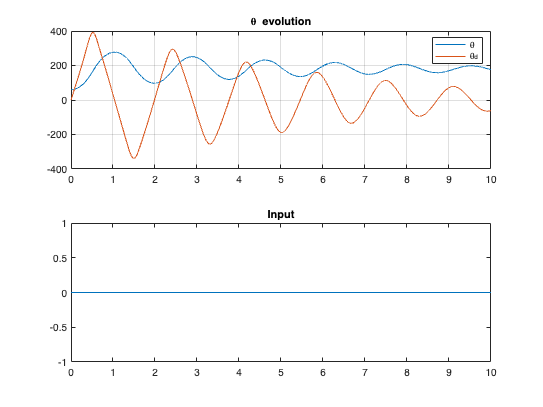

x0 = [pi/3 0 0 0];
dt = 0.001;
T = 10;
t = 0:dt:T;
theta = [x0(1) zeros(1,length(t)-1)];
xc = [x0(2) zeros(1,length(t)-1)];
dtheta = [x0(3) zeros(1,length(t)-1)];
dxc = [x0(4) zeros(1,length(t)-1)];
u = zeros(1,length(t));
for i = 2:length(t)
  %ddtheta = (3*(- L*m*cos(theta)*sin(theta)*dtheta^2 - u*cos(theta) + g*m*sin(theta) + M*g*sin(theta) + bc*dxc*cos(theta)))/(L*(- 3*m*cos(theta)^2 + 4*M + 4*m));
  %ddxc    = (4*L*m*sin(theta)*dtheta^2 + 4*u - 4*bc*dxc - 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);

  [ddtheta, ddxc] = getdstate(theta(i-1), xc(i-1), dtheta(i-1), dxc(i-1), u(i-1), M, m, L, g, bp, bc);
  [x1, x2, x3, x4] = getstate(dt, theta(i-1), xc(i-1), dtheta(i-1), dxc(i-1), ddtheta, ddxc);

  
  dtheta(i) = x3;%dtheta(i-1)+ddtheta*dt;
  dxc(i) = x4;%dxc(i-1)+ddxc*dt;
  theta(i) = x1;%theta(i-1)+dtheta(i)*dt;
  xc(i) = x2;%xc(i-1)+dxc(i-1)*dt;
end
figure;
subplot(2,1,1);
plot(t,180/pi*mod(theta,2*pi));
hold on;
grid on;
plot(t,180/pi*dtheta);
l = legend('\theta','\theta_d');
title('\theta evolution');
subplot(2,1,2);
plot(t,u);
title('Input');

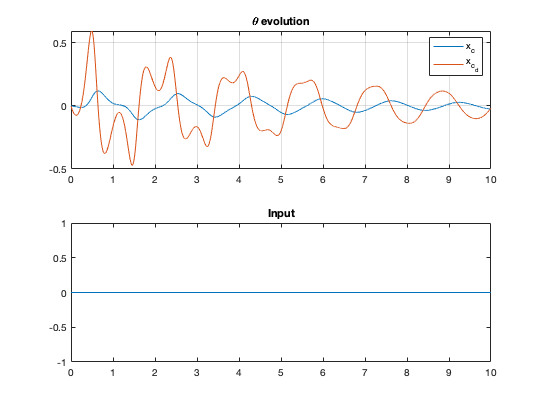

figure;
subplot(2,1,1);
plot(t,xc);
hold on;
grid on;
plot(t,dxc);
l = legend('x_c','x_{c_d}');
title('\theta evolution');
subplot(2,1,2);
plot(t,u);
title('Input');

## Linearization

syms theta xc dtheta dxc;
x0 = [0 0 0 0];
f_1 = dtheta;
f_2 = dxc;
f_3 = (3*(M*bp*dtheta - m*u*cos(theta) + g*m^2*sin(theta) + bp*dtheta*m + M*g*m*sin(theta) + bc*dxc*m*cos(theta) - L*dtheta^2*m^2*cos(theta)*sin(theta)))/(L*m*(- 3*m*cos(theta)^2 + 4*M + 4*m));
f_4 = -(- 4*L*m*sin(theta)*dtheta^2 + 3*bp*cos(theta)*dtheta - 4*u + 4*bc*dxc + 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);-(- 4*L*m*sin(theta)*dtheta^2 + 3*bp*cos(theta)*dtheta - 4*u + 4*bc*dxc + 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);

format bank;
A = [subs(diff(f_1, theta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_1, dtheta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_1, p), [theta, xc, dtheta, dxc] , x0) subs(diff(f_1, dp), [theta, xc, dtheta, dxc] , x0);
     subs(diff(f_2, theta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_2, dtheta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_2, p), [theta, xc, dtheta, dxc] , x0) subs(diff(f_2, dp), [theta, xc, dtheta, dxc] , x0);    
     subs(diff(f_3, theta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_3, dtheta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_3, p), [theta, xc, dtheta, dxc] , x0) subs(diff(f_3, dp), [theta, xc, dtheta, dxc] , x0);
     subs(diff(f_4, theta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_4, dtheta), [theta, xc, dtheta, dxc] , x0) subs(diff(f_4, p), [theta, xc, dtheta, dxc] , x0) subs(diff(f_4, dp), [theta, xc, dtheta, dxc] , x0)
];

Unrecognized function or variable 'p'.

A = eval(A);
B = [subs(diff(f_1, u),[theta, xc, dtheta, dxc] , x0);
     subs(diff(f_2, u),[theta, xc, dtheta, dxc] , x0);
     subs(diff(f_3, u),[theta, xc, dtheta, dxc] , x0);
     subs(diff(f_4, u),[theta, xc, dtheta, dxc] , x0)
     ];
B = eval(B);

[M Lambda] = eig(A)
for i=1:4
    disp(['Re(lambda)=',num2str(real(Lambda(i,i))),' Im(lambda)=',num2str(imag(Lambda(i,i))) ])

end


$$-{\textrm{Lb}}_p \dot{\;\theta } {\cos \left(\theta \right)}^2 +L$$


The center of gravity of the pendulum changes as the cart moves. It is given by:


$$c_{g,x} =x+\textrm{Lcos}\left(\theta \right)$$
 
$$c_{g,y} =\textrm{Lsin}\left(\theta \right)$$


Summing up the horizontal forces on the cart gives:


$$\ddot{\;x} =\frac{1}{M}\left(F-N-b_c \dot{x} \right)$$


Summin up the torque on the pendulum (using center of gravity as point of rotation) gives:


$$\ddot{\;\theta \;} =\frac{1}{J_p }\left(-L\;N\;\cos \left(\theta \right)+L\;P\;\sin \left(\theta \;\right)-b_p \dot{\theta \;} \right)$$


Summing up the forces on the pendulum in each direction gives:

y) $P-\textrm{mg}=m\;L\;\ddot{\;\sin \left(\theta \right)}$ 


$$\frac{\mathrm{d}}{\mathrm{d}t}\cos \left(\theta \right)\;=-\sin \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}t}\theta =-\sin \left(\theta \right)\dot{\;\theta } \Rightarrow \frac{d^2 }{\mathrm{d}t^2 }\cos \left(\theta \right)=-\sin \left(\theta \right)\ddot{\;\theta } -\cos \left(\theta \right){\;\dot{\;\theta \;} }^2$$



$$P=\textrm{mg}-\textrm{mL}\left(\sin \left(\theta \right)\ddot{\;\theta } +\cos \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)$$


x) $N=m\ddot{x} +\textrm{mL}\ddot{\;\sin \left(\theta \;\right)}$


$$\frac{\mathrm{d}}{\mathrm{d}t}\sin \left(\theta \right)\;=\cos \left(\theta \right)\frac{\mathrm{d}}{\mathrm{d}t}\theta =\cos \left(\theta \right)\dot{\;\theta } \Rightarrow \frac{d^2 }{\mathrm{d}t^2 }\sin \left(\theta \right)=\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2$$



$$N=m\ddot{\;x} +\textrm{mL}\left(\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)$$


Combining the equations gives:


$$\ddot{\;x} =\frac{1}{M}\left(F-\left(m\ddot{\;x} +\textrm{mL}\left(\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)\right)-b_c \dot{x} \right)$$



$$\Leftrightarrow \ddot{\;x} =\frac{1}{M+m}\left(F-m\;L\left(\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)-b_c \dot{x} \right)$$



$$\ddot{\;\theta \;} =\frac{1}{J_p }\left(-L\;\left(m\ddot{\;x} +\textrm{mL}\left(\cos \left(\theta \right)\ddot{\;\theta } -\sin \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)\right)\;\cos \left(\theta \right)+L\;\left(\textrm{mg}-\textrm{mL}\left(\sin \left(\theta \right)\ddot{\;\theta } +\cos \left(\theta \right){\;\dot{\;\theta \;} }^2 \right)\right)\;\sin \left(\theta \;\right)-b_p \dot{\theta \;} \right)$$



$$\Leftrightarrow J_p \ddot{\;\theta } +{\textrm{mL}}^2 {\cos \left(\theta \right)}^2 \ddot{\;\theta } +{\textrm{mL}}^2 {\sin \left(\theta \right)}^2 \ddot{\;\theta \;} =\ddot{\;\theta } \left(J_p +{\textrm{mL}}^2 \right)=-L\;\left(m\ddot{\;x} -\textrm{mLsin}\left(\theta \right){\;\dot{\;\theta \;} }^2 \right)\;\cos \left(\theta \right)+L\;\left(\textrm{mg}-\textrm{mLcos}\left(\theta \right){\;\dot{\;\theta \;} }^2 \right)\;\sin \left(\theta \;\right)-b_p \dot{\theta \;}$$



$$\Leftrightarrow \ddot{\;\theta } \left(J_p +{\textrm{mL}}^2 \right)=-L\;m\ddot{\;x} \cos \left(\theta \right)+m\;L^2 \sin \left(\theta \;\right){\;\dot{\;\theta \;} }^2 \cos \left(\theta \right)-L\;m\;g\;\sin \left(\theta \right)-L^2 \;m\;\cos \left(\theta \right){\;\dot{\;\theta \;} }^2 \;\sin \left(\theta \;\right)-b_p \dot{\theta \;}$$



$$\Leftrightarrow \ddot{\;\theta } \left(J_p +{\textrm{mL}}^2 \right)=-L\;m\ddot{\;x} \cos \left(\theta \right)-L\;m\;g\;\sin \left(\theta \right)-b_p \dot{\theta \;}$$


syms x dx ddx 

# Inverted pendulum model without friction

Non linear model:


$$\dot{\;\mathit{\mathbf{x}}} =\left\lbrack \begin{array}{c}
f_1 \left(\mathit{\mathbf{x}},u\right)\\
f_2 \left(\mathit{\mathbf{x}},u\right)\\
f_3 \left(\mathit{\mathbf{x}},u\right)\\
f_4 \left(\mathit{\mathbf{x}},u\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{\;\theta \;} \\
\dot{\;p} \\
\dot{\frac{1}{M+m-\frac{3}{4}m\;{\cos \left(\theta \right)}^2 }\left(\frac{3g}{4L}\left(M+m\right)\sin \left(\theta \right)-\frac{3m}{4}{\dot{\;\theta \;} }^2 \sin \left(\theta \right)\cos \left(\theta \right)-\frac{3}{4L}u\;\cos \left(\theta \right)\right)} \\
\frac{1}{M+m-\frac{3}{4}m\;{\cos \left(\theta \right)}^2 }\left({\dot{\;\theta \;} }^2 \textrm{mLsin}\left(\theta \right)-\frac{3}{4}\textrm{mgsin}\left(\theta \right)\cos \left(\theta \right)+u\right)
\end{array}\right\rbrack$$



$$y=p$$



$$\mathit{\mathbf{x}}=\left\lbrack \begin{array}{c}
\theta \\
p\\
\dot{\;\theta \;} \\
\dot{p} 
\end{array}\right\rbrack$$


disp('ddtheta= ')
sol.ddtheta
disp('ddxc= ')
sol.ddxc

### Parameters and intialization

clear all;
x0 = [30*pi/180 0 0 0];
M = 2;
m = 1;
L = 0.5;
g = 9.82;
Jp = 1/12*m*L^2;
bp = 0;
bc = 1;
sine_wave = 0;
sine_amp = 2;
sine_freq = 0.1;
frc = 3/4;

### Simulation

if(sine_wave == 1)
    sim('invpend_m', 20)
else
    T = 100;
    t = 0:0.0001:T;
    inp = zeros(length(t),2);
    inp(:,1) = t;
    t_step = 0.1;
    step = zeros(length(t), 1);
    step(1:fix(t_step/0.001)-1) = 0;
    step(fix(t_step/0.001):end) = 0;
    inp(:,2) = step;
    sim('invpend_m',T,[],inp);
end

### Linearization

syms theta dtheta p dp u;
f_1 = dtheta;
f_2 = 1/(M + m -3/4*m*(cos(theta))^2)*(3*g/(4*L)*(M+m)*sin(theta) - 3/4*m*dtheta^2*sin(theta)*cos(theta) - 3/(4*L)*u*cos(theta));
f_3 = dp;
f_4 = 1/(M + m -3/4*m*(cos(theta))^2)*(dtheta^2*m*L*sin(theta) - 3/4*m*g*sin(theta)*cos(theta)+u);
format bank;
A = [subs(diff(f_1, theta), [theta, dtheta, p, dp] , x0) subs(diff(f_1, dtheta), [theta, dtheta, p, dp] , x0) subs(diff(f_1, p), [theta, dtheta, p, dp] , x0) subs(diff(f_1, dp), [theta, dtheta, p, dp] , x0);
     subs(diff(f_2, theta), [theta, dtheta, p, dp] , x0) subs(diff(f_2, dtheta), [theta, dtheta, p, dp] , x0) subs(diff(f_2, p), [theta, dtheta, p, dp] , x0) subs(diff(f_2, dp), [theta, dtheta, p, dp] , x0);    
     subs(diff(f_3, theta), [theta, dtheta, p, dp] , x0) subs(diff(f_3, dtheta), [theta, dtheta, p, dp] , x0) subs(diff(f_3, p), [theta, dtheta, p, dp] , x0) subs(diff(f_3, dp), [theta, dtheta, p, dp] , x0);
     subs(diff(f_4, theta), [theta, dtheta, p, dp] , x0) subs(diff(f_4, dtheta), [theta, dtheta, p, dp] , x0) subs(diff(f_4, p), [theta, dtheta, p, dp] , x0) subs(diff(f_4, dp), [theta, dtheta, p, dp] , x0)
];
A = eval(A);
% Note: everything in terms of u is already linear, so operating point u0
% is redundant

B = [subs(diff(f_1, u),[theta, dtheta, p, dp] , x0);
     subs(diff(f_2, u),[theta, dtheta, p, dp] , x0);
     subs(diff(f_3, u),[theta, dtheta, p, dp] , x0);
     subs(diff(f_4, u),[theta, dtheta, p, dp] , x0)
     ];
B = eval(B);

[M Lambda] = eig(A)
for i=1:4
    disp(['Re(lambda)=',num2str(real(Lambda(i,i))),' Im(lambda)=',num2str(imag(Lambda(i,i))) ])

end

function [ddtheta, ddxc] = getdstate(theta, xc, dtheta, dxc, u, M, m, L, g,  bp, bc)
%   ddtheta = (3*(- L*m*cos(theta)*sin(theta)*dtheta^2 - u*cos(theta) + g*m*sin(theta) + M*g*sin(theta) + bc*dxc*cos(theta)))/(L*(- 3*m*cos(theta)^2 + 4*M + 4*m));
%   ddxc    = (4*L*m*sin(theta)*dtheta^2 + 4*u - 4*bc*dxc - 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);
%   
  ddtheta = (3*(M*bp*dtheta - m*u*cos(theta) + g*m^2*sin(theta) + bp*dtheta*m + M*g*m*sin(theta) + bc*dxc*m*cos(theta) - L*dtheta^2*m^2*cos(theta)*sin(theta)))/(L*m*(- 3*m*cos(theta)^2 + 4*M + 4*m));
  ddxc    = -(- 4*L*m*sin(theta)*dtheta^2 + 3*bp*cos(theta)*dtheta - 4*u + 4*bc*dxc + 3*g*m*cos(theta)*sin(theta))/(- 3*m*cos(theta)^2 + 4*M + 4*m);

%   ddtheta = 1/(L * m * (-3 * m * cos(theta)^2 + 4 * M + 4 * m))                        * ...
%             (3 * (M * bp * dtheta - m * u * cos(theta)                                 + ...
%             g * m^2 * sin(theta)                                                       + ...
%             bp * dtheta * m                                                            + ...
%             M * g * m * sin(theta)                                                     + ...
%             bc * dxc * m * cos(theta) - L * dtheta^2 * m^2 * cos(theta) * sin(theta))) ;
% 
%   ddxc    = -1/(-3 * m * cos(theta)^2 + 4 * M + 4 * m)                                 * ...
%             (-4 * L * m * sin(theta) * dtheta^2                                        + ...
%             3 * bp * cos(theta) * dtheta                                               - ...
%             4 * u                                                                      + ...
%             4 * bc * dxc                                                               + ...
%             3 * g * m * cos(theta) * sin(theta))                                       ;
end

function [theta, xc, dtheta, dxc] = getstate(dt, theta_p, xc_p, dtheta_p, dxc_p, ddtheta, ddxc)

   dtheta = dtheta_p + ddtheta * dt;

   dxc    = dxc_p    + ddxc    * dt;

   theta  = theta_p  + dtheta  * dt;

   xc     = xc_p     + dxc     * dt;
end

%[theta(i), xc(i), dtheta(i), dxc(i)] = getstate(dt, theta(i-1), xc(i-1), dtheta(i-1), dxc(i-1), ddtheta, ddxc);

%{
    Algorithm for simulating the system.
    Init:
    Get x0.
    Calculate first dx.
    Get x = dx*dt.
    Calculate new dx.
    get x = dx*dt.

%}

## Functions